## ROBOTICS PROJECT

clear all
close all

figure_index = 1;

% compute standard trajectories using simulink or load it
traj_sim = false;

Definizione degli agenti, posizioni casuali e orientamenti casuali  (3D)

settare la comunicazione con handshaking (common network)

*definizione: fatto*

*manca settare la rete *

% initialize UGV struct
ugv.xw = 0;  ugv.yw = 0; ugv.hw = -pi/4;    % robot position and orientation wrt world frame
ugv.xr = 0;  ugv.yr = 0; ugv.hr = 0;    % robot position and orientation wrt its frame

% define position of visual features of UGV
ugv.P1 = [0.2; 0.15; 0.2];      %[m]
ugv.P2 = [0.2; -0.15; 0.2];     %[m]
ugv.P3 = [-0.2; -0.15; 0.2];    %[m]
ugv.P4 = [-0.2; 0.15; 0.2];     %[m]

% !!! pose wrt its frame is needed only to have the right arrays and matrices dimension

% initialize AUV struct 


formation.alt = 3;                      % formation altitude
formation.r = 3;                        % formation radius
formation.offset = 0.3;                 % altitude and radius offset to perform large movement 
formation.search_alt = 2.5;             % altitude for ugv search operation
formation.search_turn = 0.2;            % turn rate while searching the ugv
formation.search_move = 0.1;            % speed rate while searching ugv


auv.n  = 7;                             % number of auvs
    
auv.id =    zeros(auv.n,1);             % auv id 
auv.xw =    rand(auv.n,1)*6-3 ;         % coords in world frame
auv.yw =    rand(auv.n,1)*6-3 ;
auv.zw =    0.1*ones(auv.n,1);

auv.rollw  =  zeros(auv.n,1);           % roll angle in world frame
auv.pitchw =  zeros(auv.n,1);           % pitch angle in world frame
auv.yaww   =  rand(auv.n,1)*2*pi;       % yaw angle in world frame

auv.xr = auv.xw - ugv.xw;               % coords in robot frame (UGV)
auv.yr = auv.yw - ugv.yw;  
auv.zr = auv.zw; 

auv.rollr = auv.rollw ;                 % we suppose initial roll and pitch
auv.pitchr = auv.pitchw;                % angles will always be zero, only
auv.yawr = auv.yaww - ugv.hw;           % yaw angle may be different

auv.search_inc = zeros(auv.n,1);        % search iterations increments      


% camera parameters:

cam.fov.x = 1.2572;                                 % vertical  fov [rad]
cam.fov.y = 1.4408;                                 % orizontal fov [rad]
cam.f = 3.6*10^-3;                                  % focal length  [m]
cam.ImagePlaneSize = [6.32*10^-3  4.74*10^-3];      % Y x X         [m  m]
cam.PixelDensity = [4000  3000];                    % Y x X - adimensional


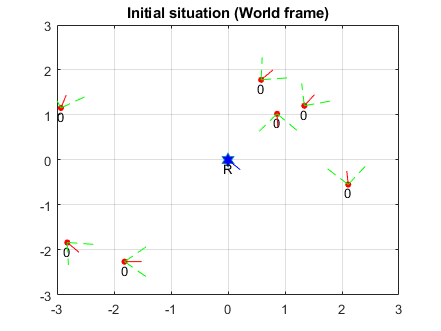

%% visualize the initial situation

% generate labels for plot
labels = generateLabels(auv);

% plot the situation
figure(figure_index);
figure_index = figure_index+1;
plotFlock(auv,ugv,cam,labels);
axis([-3 3 -3 3]);
grid on;

title('Initial situation (World frame)');

Definizione traiettoria ugv, e generiamo la traiettoria controllata da simulink (2D)

*fatto (volendo migliorare il controllore di simulink)*

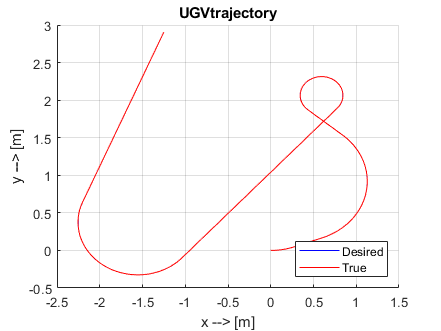

% Run UGV_init (./trajectories_and_controllers) for more details!

% Initialize the Unicycle model
run initializeUnicycleModel.m

% Generate the trajectory
run UGV_trajectory_generation.m

% Set the controller parameters
run UGV_ctrl_params.m

%% simulate
if traj_sim
    open_system('UGV_21a.slx');
    UGVRealPose = sim('UGV_21a.slx', 'ReturnWorkspaceOutputs', 'on');
else
    load("data\UGVRealPose.mat");
end

figure(figure_index);
figure_index = figure_index+1;
hold on
plot(ugv.trajectory.signals.values(:,1), ugv.trajectory.signals.values(:,2), 'b');
%axis([-3 2 -0.5 3]);
grid on;
title('UGVtrajectory');
legendInfo=string(zeros(2,1));
legendInfo(1, 1) = sprintf('Desired');

% plot real trajectory of the ugv
plot(UGVRealPose.Pose.signals.values(:,1), UGVRealPose.Pose.signals.values(:,2), 'r');
legendInfo(2, 1) = sprintf('True');

legend(legendInfo(:,:),'Location','SouthEast');
xlabel('x --> [m]')
ylabel('y --> [m]')

definizione decollo degli uav e generazione trajectory in simulink (3D)

*fatto*  

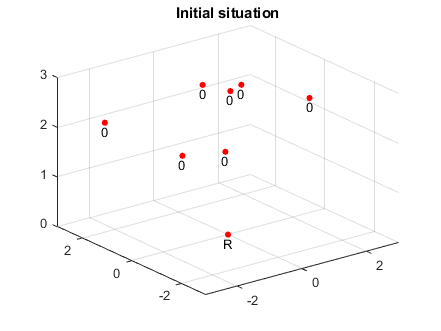

% take off
auv.zr = formation.search_alt * ones(auv.n,1);
auv.zw = auv.zr;

%% we create a UAVSimulationVECTOR as a vector of signals that holds the
% wanted trajectory that each uav must follow. This trajectory is defined
% wrt the initial frame of each UAV
T=50;
UAVSimulation.signals.values = zeros((T-30)/Ts, 4);  % [x, y, z, yaw]
UAVSimulation.time = zeros((T-30)/Ts,1);
%for i=1:1:size(UAVSimulation.time,1)
%    UAVSimulation.time(i)= Ts*i;
%end

UAVSimulationVECTOR = [UAVSimulation UAVSimulation];

for auv_idx=3:auv.n
    UAVSimulationVECTOR = [UAVSimulationVECTOR UAVSimulation];
end

index = 0;
% simulate take-off in 1.5 second
Pose=[0 0 0 0];     % [x, y, z, yaw] initial
NextPose=[0 0 auv.zr(1) 0]; % [x, y, z, yaw] after take-off
elapsed_time = 1.5;
Trajectory = computeUAVTrajectory(Pose,NextPose,elapsed_time);

for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(1:size(Trajectory,1),:) = Trajectory(:,1:4);
    for i=1:1:size(Trajectory,1)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

%% visualize the situation after take-off (simulated)
figure(figure_index);
figure_index = figure_index+1;
plot3([auv.xr; ugv.xr],[auv.yr; ugv.yr],[auv.zr; 0],'or','MarkerSize',4,'MarkerFaceColor','r')
text([auv.xr; ugv.xr],[auv.yr; ugv.yr],[auv.zr; 0],labels,'VerticalAlignment','top','HorizontalAlignment','center')
axis([-3 3 -3 3])   
title('Initial situation');
grid on;

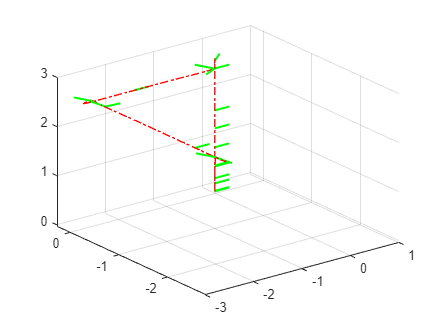


%--------------------------------------------------%

% simulate search in 4.5 second (turn around)
index = elapsed_time / Ts + 1;
Pose=Trajectory(index-1, 1:4);      % [x, y, z, yaw] initial
NextPose=[0 0 auv.zr(1) 2*pi]; % [x, y, z, yaw] after take-off
elapsed_time = 4.5;    
Trajectory = computeUAVTrajectory(Pose,NextPose,elapsed_time);

for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(index:(size(Trajectory,1)+index-1),:) = Trajectory(:,1:4);
    for i=index:1:(size(Trajectory,1)+index)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

%--------------------------------------------------%

% simulate search in 3 second (go backward)
index = index +  elapsed_time / Ts ;
Pose=Trajectory((elapsed_time / Ts), 1:4);      % [x, y, z, yaw] initial
NextPose=[-2.5 0 auv.zr(1) 2*pi];               % [x, y, z, yaw] 
elapsed_time =3;    
Trajectory = computeUAVTrajectory(Pose,NextPose,elapsed_time);
for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(index:(size(Trajectory,1)+index-1),:) = Trajectory(:,1:4);
    for i=index:1:(size(Trajectory,1)+index)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

%--------------------------------------------------%

% simulate search in 4.5 second (turn around, other direction)
index = index +  elapsed_time / Ts ;
Pose=Trajectory((elapsed_time / Ts), 1:4);      % [x, y, z, yaw] initial
NextPose=[-2.5 0 auv.zr(1) 0]; % [x, y, z, yaw] after take-off
elapsed_time = 4.5;    
Trajectory = computeUAVTrajectory(Pose,NextPose,elapsed_time);

for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(index:(size(Trajectory,1)+index-1),:) = Trajectory(:,1:4);
    for i=index:1:(size(Trajectory,1)+index)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

%--------------------------------------------------%

% simulate search in 3 second (go leftwards)
index = index +  elapsed_time / Ts ;
Pose=Trajectory((elapsed_time / Ts), 1:4);      % [x, y, z, yaw] initial
NextPose=[-2.5 -2.5 auv.zr(1) 0];               % [x, y, z, yaw] 
elapsed_time =3;    
Trajectory = computeUAVTrajectory(Pose,NextPose,elapsed_time);
for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(index:(size(Trajectory,1)+index-1),:) = Trajectory(:,1:4);
    for i=index:1:(size(Trajectory,1)+index)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

%--------------------------------------------------%

% simulate search in 4.5 second (turn around)
index = index +  elapsed_time / Ts ;
Pose=Trajectory((elapsed_time / Ts), 1:4);      % [x, y, z, yaw] initial
NextPose=[-2.5 -2.5 auv.zr(1) 2*pi]; % [x, y, z, yaw] after take-off
elapsed_time = 4.5;    
Trajectory = computeUAVTrajectory(Pose,NextPose,elapsed_time);

for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(index:(size(Trajectory,1)+index-1),:) = Trajectory(:,1:4);
    for i=index:1:(size(Trajectory,1)+index)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

%--------------------------------------------------%

% if not found, go back home
index = index +  elapsed_time / Ts ;
Pose=Trajectory((elapsed_time / Ts), 1:4);      % [x, y, z, yaw] initial
NextPose=[0 0 0 2*pi]; % [x, y, z, yaw] after take-off
elapsed_time = 4.9;    
Trajectory = computeUAVTrajectory(Pose,NextPose,elapsed_time);

for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(index:(size(Trajectory,1)+index-1),:) = Trajectory(:,1:4);
    for i=index:1:(size(Trajectory,1)+index)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

index = index +  elapsed_time / Ts ;
Pose=Trajectory((elapsed_time / Ts), 1:4);      % [x, y, z, yaw] initial
NextPose=[0 0 0 2*pi]; % [x, y, z, yaw] after take-off
elapsed_time = 0.1;    
Trajectory = computeUAVTrajectory(Pose,NextPose,elapsed_time);

for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(index:(size(Trajectory,1)+index-1),:) = Trajectory(:,1:4);
    for i=index:1:(size(Trajectory,1)+index)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

%---------------------------------------------------%
%---------------------------------------------------%

run initializeQuadrotorModel.m
%run UAV_trajectory_generation.m
% Set the controller parameters
run UAV_ctrl_params.m

clear p_ref;
clear yaw_ref;
 
for j=1:size(UAVSimulationVECTOR(1).signals.values,1)
        p_ref.signals.values(j,1) = UAVSimulationVECTOR(1).signals.values(j,1);
        p_ref.signals.values(j,2) = UAVSimulationVECTOR(1).signals.values(j,2);
        p_ref.signals.values(j,3) = UAVSimulationVECTOR(1).signals.values(j,3);
        yaw_ref.signals.values(j,1) = UAVSimulationVECTOR(1).signals.values(j,4);
end
p_ref.time = UAVSimulationVECTOR(1).time(1:j,:);
yaw_ref.time = UAVSimulationVECTOR(1).time(1:j,:);

if traj_sim
    open_system('UAV_2021_a.slx');
    UAVRealPose = sim('UAV_2021_a.slx', 'ReturnWorkspaceOutputs', 'on');
else
    load("data\UAVRealPose.mat");
end

% plot
figure(figure_index);
figure_index = figure_index+1;
title('UAVtrajectory');
legendInfo=string(zeros(2,1));
legendInfo(1, 1) = sprintf('Desired');
legendInfo(2, 1) = sprintf('True');

% plot real trajectory
plot3(UAVRealPose.Pose.signals.values(:,1), UAVRealPose.Pose.signals.values(:,2), UAVRealPose.Pose.signals.values(:,3), 'r-.', 'LineWidth', 1);
hold on
grid on
% and also yaw angle (occasionally)
for j=1:20:100
    UAV_xd = UAVRealPose.Pose.signals.values(j,1) + 0.3*cos(UAVRealPose.Pose.signals.values(j,6));
    UAV_yd = UAVRealPose.Pose.signals.values(j,2) + 0.3*sin(UAVRealPose.Pose.signals.values(j,6));
    plot3([UAVRealPose.Pose.signals.values(j,1) UAV_xd], [UAVRealPose.Pose.signals.values(j,2) UAV_yd], [UAVRealPose.Pose.signals.values(j,3) UAVRealPose.Pose.signals.values(j,3)], 'g', 'LineWidth', 1.5);
end
for j=101:100:401
    UAV_xd = UAVRealPose.Pose.signals.values(j,1) + 0.3*cos(UAVRealPose.Pose.signals.values(j,6));
    UAV_yd = UAVRealPose.Pose.signals.values(j,2) + 0.3*sin(UAVRealPose.Pose.signals.values(j,6));
    plot3([UAVRealPose.Pose.signals.values(j,1) UAV_xd], [UAVRealPose.Pose.signals.values(j,2) UAV_yd], [UAVRealPose.Pose.signals.values(j,3) UAVRealPose.Pose.signals.values(j,3)], 'g', 'LineWidth', 1.5);
end
for j=401:200:(size(UAVRealPose.Pose.signals.values,1))
    UAV_xd = UAVRealPose.Pose.signals.values(j,1) + 0.3*cos(UAVRealPose.Pose.signals.values(j,6));
    UAV_yd = UAVRealPose.Pose.signals.values(j,2) + 0.3*sin(UAVRealPose.Pose.signals.values(j,6));
    plot3([UAVRealPose.Pose.signals.values(j,1) UAV_xd], [UAVRealPose.Pose.signals.values(j,2) UAV_yd], [UAVRealPose.Pose.signals.values(j,3) UAVRealPose.Pose.signals.values(j,3)], 'g', 'LineWidth', 1.5);
end


%---------------------------------------------%
%---------------------------------------------%

% create a variable containing the result, like UAVSimulationVECTOR, 1 for
% each drone
% RELATIVE (UAV FRAME)

UAVRealPoseVECTOR=[UAVRealPose UAVRealPose];

for auv_idx=3:auv.n
    UAVRealPoseVECTOR = [UAVRealPoseVECTOR UAVRealPose];
end

% ABSOLUTE (UGV FRAME)

UAVRealPoseVECTOR_abs = UAVRealPoseVECTOR;

for auv_idx=1:auv.n
    UAVRealPoseVECTOR_abs(1,auv_idx).Pose.signals.values = UAVRealPoseVECTOR_abs(1,auv_idx).Pose.signals.values + [auv.xw(auv_idx) auv.yw(auv_idx) auv.zw(auv_idx) auv.rollw(auv_idx) auv.pitchw(auv_idx) auv.yaww(auv_idx)];
end

I droni cercano di vedere l'ugv con la telecamera con movimenti e rotazioni casuali (3D)

dal momento in cui un drone vede l'ugv, lo comunica, ed entra nella rete di formazione (formation network)

*da aggiungere: *

*-la semplice rotazione basta per trovare il robot prima o poi, ma se il drone è stato spawnato troppo vicino al robot, non lo vedrà mai, perchè il robot si trova esattamente sotto di lui.*

*Si potrebbe aggiungere che se dopo aver fatto il giro completo su se stesso, il drone ancora non vede il robot, indietreggia di tot m, e ricomincia a girare.*

*- lo schema e il calcolo del grafo con le varie matrici ogni volta che la formazione (quindi la rete) cambia perchè si è aggiunto qualcuno.*

% create two auv structures: out_auv struct for the auvs that don't see the
% ugv yet and form_auv for the auvs that see the ugv and so can go in formation.
out_auv = auv;
form_auv.n = 0;

for i = 1 : out_auv.n
    out_auv.real_traj(i) = UAVRealPoseVECTOR_abs(1,i);
end




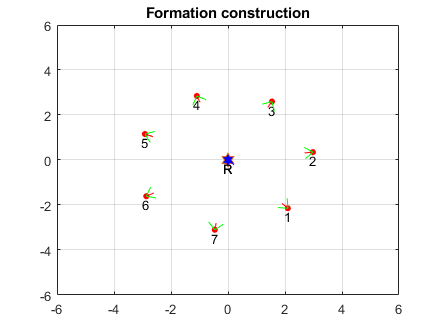


update_formation = false;
form_complete = false;

max_it = 399;
it = 1;
time = 10;
T1 = 0.01;


% auv search the robot
while(form_auv.n~=auv.n || form_complete == false)
    
    labels_out = generateLabels(out_auv);
    labels_form = generateLabels(form_auv);
    
    out_auv = rel2glob(out_auv,ugv);
    
    figure(figure_index);
    plotFlock(out_auv,ugv,cam,labels_out);
    hold on;
    plotFlock(form_auv,ugv,cam,labels_form);
    hold off;
    lim = formation.r  * 2;
    axis([-lim lim -lim lim ]);
    grid on;
    title("Formation construction")
    it=it+1;
 
    pause(.01)
    
    %% --------------- AUVS NOT IN FORMATION
    % check if auvs not in formation see the robot
    rem = [];
    out_auv = glob2rel(out_auv, ugv);
    for i = 1 : out_auv.n
        
        % use simulation data
        out_auv.xr(i) = out_auv.real_traj(1,i).Pose.signals.values(time,1);
        out_auv.yr(i) = out_auv.real_traj(1,i).Pose.signals.values(time,2);
        out_auv.zr(i) = out_auv.real_traj(1,i).Pose.signals.values(time,3);
        
        out_auv.rollr(i) = out_auv.real_traj(1,i).Pose.signals.values(time,4);
        out_auv.pitchr(i) = out_auv.real_traj(1,i).Pose.signals.values(time,5);
        out_auv.yawr(i) = out_auv.real_traj(1,i).Pose.signals.values(time,6);
        
        % Check if the auv see the ugv 
        auv_pos = [out_auv.xr(i) out_auv.yr(i) out_auv.zr(i)];
        auv_rpy = [out_auv.rollr(i) out_auv.pitchr(i) out_auv.yawr(i)];
        
        [is_inside1,x1,y1] = computeCameraImage(auv_pos,auv_rpy,ugv.P1.');
        [is_inside2,x2,y2] = computeCameraImage(auv_pos,auv_rpy,ugv.P2.');
        [is_inside3,x3,y3] = computeCameraImage(auv_pos,auv_rpy,ugv.P3.');
        [is_inside4,x4,y4] = computeCameraImage(auv_pos,auv_rpy,ugv.P4.');
    
        if(is_inside1 && is_inside2 && is_inside3 && is_inside4)    
         
        % retrieve its relative position with camera data and add to the formation
            [droneLocation,droneOrientation] = PoseReconstruction([x1 y1; x2 y2; x3 y3; x4 y4]);
            
            out_auv.xr(i) = droneLocation(1);
            out_auv.yr(i) = droneLocation(2);
            out_auv.zr(i) = droneLocation(3);
            out_auv.yawr(i) = atan2(droneOrientation(3,2),droneOrientation(3,3));
            
            out_auv.id(i) = form_auv.n+1;
            form_auv = addToFormation(form_auv,out_auv,i);
            rem(end+1) = i;    
            update_formation = true;
            it = 1;
        end
    end

    out_auv = removeAuvFrom(out_auv, rem);

        
    %% --------------- AUVS IN FORMATION
    if(form_auv.n > 1) 
        form_auv = consensusPolarFormation(form_auv,ugv,formation,update_formation,0.1);
        
        % store the desired trajectory
        for i = 1 : form_auv.n
            form_auv.record(i).data(time/10, :) = [ form_auv.xr(i) form_auv.yr(i) form_auv.zr(i) form_auv.yawr(i) T1 time*T1];
        end
        
        update_formation = false;
        
        if(max(form_auv.travel_dist) < 0.05 && max(form_auv.th_err) < 0.05)
            form_complete = true;         
        else
            form_complete = false;
        end
    end
    
    if(it == max_it)
        break;
    end
    
    time = time + 10;
end


figure_index = figure_index+1;

if(form_auv.n==auv.n && form_complete == true)
    fprintf('Every auv is in formation after %d iterations',it);
elseif(form_auv.n~=auv.n && form_complete == true)
    fprintf('Formation complete with some auv missing after %d iterations',it);
elseif(form_auv.n==auv.n && form_complete == false)
    fprintf('Every auvs is pointing to the robot but the formation is not ready %d iterations',it);
else
    fprintf('Fail after max iterations, try to increase max_it')    
end

Every auv is in formation after 139 iterations

#### ciclo: (ogni 0.5 s consenso sul movimento UGV, e per ora verificare quanto si rovina la formazione, poi, aggiungere consenso formazione ogni tot)

COPIA E INCOLLA DA JACOPO

% estimated ugv postion in x,y directions in the 
% next iteration
estimated_after.x = zeros(form_auv.n,1);
estimated_after.y = zeros(form_auv.n,1);

% actual ugv position in x,y 
estimated_before.x = zeros(form_auv.n,1);
estimated_before.y = zeros(form_auv.n,1);

% variables that save the estimation variation of ugv
% postion in x,y between two iteration in the loop 
estimated_variation.x = zeros(form_auv.n,1);
estimated_variation.y = zeros(form_auv.n,1);

% error in y direction evaluated for each UAV in the 
% formation 
yaw_error_vector = zeros(form_auv.n, 1);

% position of the formation centre during loop
for_loop_it = 60;
formation_distance = zeros(2,for_loop_it);
% distance from ideal and actual formation centre
formation_error = zeros(1, for_loop_it);
index = 0;

%number of iteration for the consensus
n_iteration = 100;

% variable that save the trajectory to follow, coming 
% from sequence of UAVs estimation during pursuing
UAV_pursuit_trajectory = cell(for_loop_it, 2);



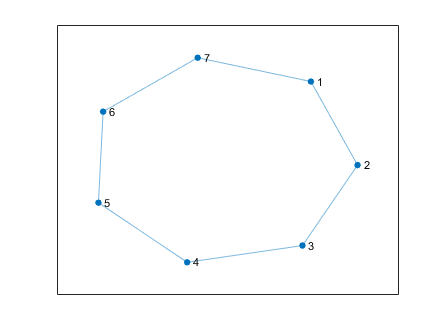

% creation of the consensus matrix
[W, G]= graph_setup(form_auv);

% plotting the graph generated
h = plot(G);
layout(h,'subspace');

close all
    

%we run an estimation outside the loop so as to consider also the first
% variation induced by the motion of the UAV
[estimated_before.x, estimated_before.y, ...
    convex_hull_estimated_before] = pose_estimation(ugv,form_auv,1);

record_data = zeros(for_loop_it,2);
ugv_before = ugv.trajectory.signals.values(1,1);


for i = 1:for_loop_it
    % we observe an iteration after 2000 steps of the UGV 
    j = i*800;
    ugv_after = ugv.trajectory.signals.values(j,1);

    [estimated_after.x, estimated_after.y,... 
        convex_hull_estimated_after, points_image_plane_y] = pose_estimation(ugv,form_auv,j);

    yaw_error_vector = -yaw_error(points_image_plane_y, form_auv);
        
    for k= 1:form_auv.n
        estimated_variation.x(k) = estimated_after.x(k) - estimated_before.x(k);
        estimated_variation.y(k) = estimated_after.y(k) - estimated_before.y(k);
    end 

    [consensus_average_x, average_x, last_consensus_x] = Consensus_iteration(n_iteration, ...
        estimated_variation.x, form_auv, W);
    [consensus_average_y, average_y, last_consensus_y] = Consensus_iteration(n_iteration, ...
        estimated_variation.y, form_auv, W);

    if i == 1
        consensus_average_plot = consensus_average_x;
    end

    index = index + 1;
   % implementation of the motion after the estimation and save the
   % trajectory in a variable
    for k= 1:form_auv.n
        UAV_pursuit_trajectory{index,1} = form_auv.xw;
        UAV_pursuit_trajectory{index,2} = form_auv.yw;
        form_auv.xw(k) = form_auv.xw(k) - last_consensus_x(k);
        form_auv.yw(k) = form_auv.yw(k) - last_consensus_y(k);
        form_auv.yawr(k) = form_auv.yawr(k) + 0.01 * yaw_error_vector(k);
    end 
    
    record_data(i,1) = last_consensus_x(1) ;
    record_data(i,2) = ugv_after-ugv_before;

    [temp_x, temp_y] = formation_centre(form_auv);

    formation_distance(1,index) = ugv.trajectory.signals.values(j,1) - temp_x;
    formation_distance(2,index) = ugv.trajectory.signals.values(j,2) - temp_y;
    formation_error(index) = sqrt((ugv.trajectory.signals.values(j,1) - temp_x)^2 ...
    +(ugv.trajectory.signals.values(j,2) - temp_y)^2);

    % update necessary to make the cycle to continously iterate 
    estimated_before.x = estimated_after.x;
    estimated_before.y = estimated_after.y;
    ugv_before = ugv_after;
end

the following UAVs do not see the UGV
     2

the following UAVs do not see the UGV
     4

the following UAVs do not see the UGV
     4

the following UAVs do not see the UGV
     4

the following UAVs do not see the UGV
     3

the following UAVs do not see the UGV
     4

the following UAVs do not see the UGV
     3

the following UAVs do not see the UGV
     4



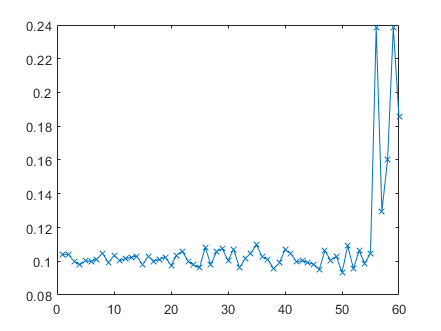

close all
% variation of the formation error in time (trigger to plot)

plot(formation_error, '-x');

close all
% distance between final formation centre and desired one;
% there also a display of the distance 

plot_actual_formation(form_auv);
hold on 
[temp_x, temp_y] = formation_centre(form_auv);
plot(temp_x, temp_y,'*');
hold on;
% here j = 40000, namely final sample og the ugv trajectory
disp(formation_error(1, 25));

    0.0961



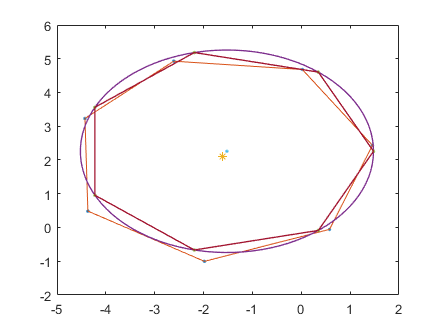

correct_formation(ugv, form_auv,j);

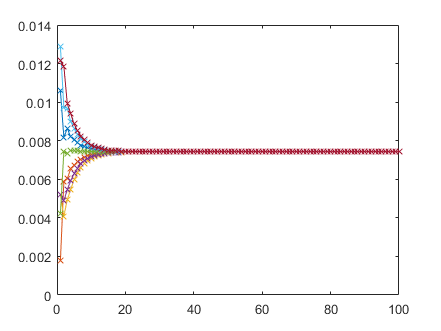

close all
% plot that show dynamics of the convergence of distributed 
% estimation between the estimation of subsequent iteration
% in the above loop (in particular last one estimation)

convergence_UAV = zeros(n_iteration ,form_auv.n); 
for i = 1 : n_iteration
    for j = 1:form_auv.n
     convergence_UAV(i,j) = consensus_average_plot{i}(j);
    end
end

for k = 1:form_auv.n
     plot(convergence_UAV(:,k), '-x')
     hold on
end

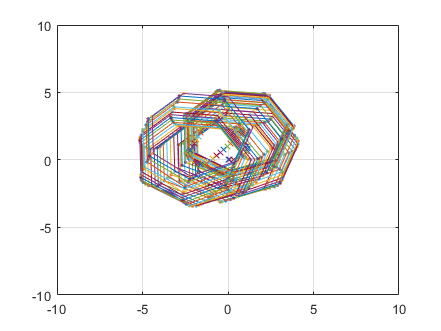

close all
% plot that consider the final result of formation motion and
% the trajectory followed by the UGV

point_x = 0;
point_y = 0;
vector_of_points = zeros(2, form_auv.n);
k = 1;
for i=1:index
    k = i*800;
    for j=1:form_auv.n

        point_x = UAV_pursuit_trajectory{i,1}(j);
        point_y = UAV_pursuit_trajectory{i,2}(j);
        vector_of_points(1, j) = point_x;
        vector_of_points(2, j) = point_y;

    end
    
    plot_with_convexhull(vector_of_points)
    axis([-10 10 -10 10])
    grid on;
    hold on
    plot(ugv.trajectory.signals.values(k,1), ...
        ugv.trajectory.signals.values(k,2), '-x');
    hold on 
    pause(.01);
end

una volta in formazione UGV si muove, 

lettura con la camera -> imageplane

imageplane -> pose recovery (misura sporca di rototransl)

*ricavare tutte le rototranslazioni e usare pose recovery che è già fatta*

consensus sulla posizione del ugv k-1 (consensus average sulla posizione del ugv dopo che si è mosso)  (2D)

*da fare *

calcolo traiettoria droni per mantenere CoM, con controllo yaw per mantere ugv all'interno dell'image plane

attuazione della traiettoria se fattibile con simulik, altrimenti, semplicemente in 2D qui

*da fare*